# Exam 1

#### AME 5763

## Blake Johnson

## Problem 1:

Consider the problem of finding the solution of the equation:


$$$\frac{d^2u}{dx^2} + u + x = 0, \quad 0 < x < 1, \quad u(0) = u(1) = 0$$$


(25 points)** Develop the weak form.

(25 points)** Assume trial $\( u(x) \) and weight \( w(x) \)$ functions with the following form:


$$$$u(x) = x(1 - x)(\alpha_1 + \alpha_2x + \cdots + \alpha_N x^{N-1}),$$$$



$$$$w(x) = x(1 - x)(\beta_1 + \beta_2x + \cdots + \beta_N x^{N-1}),$$$$


and obtain (but don’t solve) the equations to determine the unknown coefficients $\( \alpha_i \)$.

##  Problem 1 Part 1:

The governing diffeential equation is given to us as:


$$\frac{d^2u}{dx^2} + u + x = 0$$


and the displacement at $x = 0$ is the same at $x = 1$ which is zero.

To find the weak equation, multiply the governing equation by an arbitrary weight function $w(x)$:


$$w(x)\left[ \frac{d^2u}{dx^2} + u + x \right] = 0$$



$$w(x) \frac{d^2u}{dx^2} + w(x) u + w(x) x = 0$$


now to find the weak form take the integral over the given length $0 < x <1$


$$\int_0^1 \left( w(x) \frac{d^2u}{dx^2} + w(x) u + w(x) x \right) dx
$$



$$\int_0^1  w(x) \frac{d^2 u}{dx^2} dx + \int_0^1 w(x)u dx + \int_0^1 w(x)x dx = 0
$$


I used integration by parts for the first term:


$$\int_0^1  \frac{d^2 u}{dx^2} dx $$



$$u = w(x) \\du = \frac{dw}{dx} \\
v = \frac{du}{dx}\\ dv = \frac{d^{2}u}{dx^2}$$


Integration by parts: $uv - \int  v du $


$$\int_0^1  w(x) \frac{d^2 u}{dx^2} dx = \left[w(x) \frac{du}{dx}\right]_0^1 - \int_0^1 \frac{du}{dx}\frac{dw}{dx}dx$$


$u(0) = u(1) = 0$ is the boundary conditions for the problem. So whatever function $u(x)$ is, it must satisfy these conditions. 

Additionally the weight function vanishes at the boundary conditions. So $w(0) = 0 \text{ and } w(1)=0$


$$\left( w(1) \frac{du}{dx} - w(0)\frac{du}{dx}\right) = 0$$



$$\int_0^1  \frac{d^2 u}{dx^2} dx = 0 - \int_0^1 \frac{du}{dx}\frac{dw}{dx}dx$$


Now the full integral for the weak form is:


$$\int_0^1  w(x) \frac{d^2 u}{dx^2} dx + \int_0^1 w(x)u dx + \int_0^1 w(x)x dx = 0 = - \int_0^1 \frac{du}{dx}\frac{dw}{dx}dx + \int_0^1 w(x)u dx + \int_0^1 w(x)x dx = 0$$


Since the problem does not provide test functions, this is about as simplified as it can get. So the weak form is:


$$ \int_0^1 w(x)u dx + \int_0^1 w(x)x dx =  \int_0^1 \frac{du}{dx}\frac{dw}{dx}dx$$


## Part 2:

Here I want to try to input the u(x) and w(x) given in the assignment into the weak form to solve.

if we consider the trial functions:


$$u(x) = x(1-x)(\alpha_{1}+\alpha_{2}x+...+\alpha_{N}x^{N-1})\\
w(x) = x(1-x)(\beta_{1}+\beta_{2}x+...+\beta_{N}x^{N-1})\\

\frac{du}{dx} = (1-2x)((n-1)\alpha_{N}x^{N-2}+...+\alpha_{2})\\
\frac{dw}{dx} = (1-2x)((n-1)\beta_{N}x^{N-2}+...+\beta_{2})$$


and then we have:


$$ \int_0^1 w(x)u dx + \int_0^1 w(x)x dx =  \int_0^1 \frac{du}{dx}\frac{dw}{dx}dx =\\ 

\int_0^1 [x(1-x)(\beta_{1}+\beta_{2}x+...+\beta_{N}x^{N-1})][x(1-x)(\alpha_{1}+\alpha_{2}x+...+\alpha_{N}x^{N-1})] dx + \int_0^1 [x(1-x)(\beta_{1}+\beta_{2}x+...+\beta_{N}x^{N-1})]dx = \\  \int_0^1 (1-2x)^2((N-1)\alpha_{n}x^{n-2}+...+\alpha)\beta_{n}x^{n-2}+...+\beta)dx

$$


Here I could solve for $\alpha_{i}$if i knew the value. The math is a little messy for me to try and go much further. We know that the integration is going to be of some unknown exponent, so the integration will take on some form of $\int x^{exp} dx = \frac{1}{exp + 1}$ but that is about all I know to do here without an exact value.

Additionally I considered the idea that we could set the problem up this way:


$$\frac{d^2u}{dx^2} + u + x = 0 \\
\frac{d^2u}{dx^2} = -u -x\\
\int \frac{d^2u}{dx^2} dx = \int -u dx - \int x dx\\$$


Then we could integrate for and potentially solve for an $\alpha_{i}$ which would let us determine any $a_{i}$ from that point. This is what I did for homework 1 question 3.14 when I solved for $\alpha_{3}$ but I dont think that is quite a feasible as:	


$$\int_0^1 [x(1-x)(\beta_{1}+\beta_{2}x+...+\beta_{N}x^{N-1})][x(1-x)(\alpha_{1}+\alpha_{2}x+...+\alpha_{N}x^{N-1})] dx + \int_0^1 [x(1-x)(\beta_{1}+\beta_{2}x+...+\beta_{N}x^{N-1})]dx = \\  \int_0^1 (1-2x)^2((N-1)\alpha_{n}x^{n-2}+...+\alpha)\beta_{n}x^{n-2}+...+\beta)dx
$$


I went back through Chapter 2 and want to consider matirces on thsi problem as well as stiffness matrices. We can use summations to help isolate $\alpha{i}$: 

I have the weak form from Part 1, assuming the governing equation is something like a Poisson equation (I am using examplea 3.1 - 3.3 as a guide through this part):


$$\[
    \int_0^L k(x) \frac{du}{dx} \frac{dw}{dx} dx = \int_0^L f(x) w(x) dx
    \]
$$


where $u(x)$ is the displacement, $w(x)$ is the weight function, $k(x)$ is the stiffness, and $f(x)$ is a forcing function.

Now we need to introduce trial and weight functions to express $u(x)$ and $w(x)$ in terms of the unknown coefficients $\alpha_i$.


$$\[
u(x) = \sum_{i=1}^{N} \alpha_i \theta_i(x)
\]$$


where $\alpha_i$ are the unknown coefficients and $\theta_i(x)$ are the basis (shape) functions. $N$ is the number of basis functions.

Then $w(x)$ is typically chosen from the same set of functions, so we assume:


$$\[
w(x) = \sum_{j=1}^{N} \beta_j \theta_j(x)
\]$$


where $\beta_j$ are arbitrary coefficients corresponding to the weight function (I leanded heavily on chapter 2 and chapter 4,).

Next I substituted the trial function for $u(x)$ and the weight function for $w(x)$ into the weak form equation just like above:


$$\[
\int_0^L k(x) \frac{d}{dx} \left( \sum_{i=1}^{N} \alpha_i \theta_i(x) \right) \frac{d}{dx} \left( \sum_{j=1}^{N} \beta_j \theta_j(x) \right) dx = \int_0^L f(x) \sum_{j=1}^{N} \beta_j \theta_j(x) dx
\]$$


Next, I expand this expression and separate terms involving $\( \alpha_i \)$ and $\( \beta_j \)$. This has me concerned becasue the $\beta$ and $\alpha$ are combined, so I am a little unsure if this is the right direction.:

LHS:


$$\[
\sum_{i=1}^{N} \sum_{j=1}^{N} \alpha_i \beta_j \int_0^L k(x) \frac{d\theta_i}{dx} \frac{d\theta_j}{dx} dx
\]$$


RHS:


$$\[
\sum_{j=1}^{N} \beta_j \int_0^L f(x) \theta_j(x) dx
\]
$$


The coefficients $\( \beta_j \)$ are arbitrary, so I think I can separate the terms and set up a system of equations for the unknowns $\( \alpha_i \)$ (not entirely sure if this is valid though). This leads to the following system of equations for the unknown coefficients:

For $\( j = 1, 2, \dots, N \)$:


$$\[
\sum_{i=1}^{N} \alpha_i \int_0^L k(x) \frac{d\theta_i}{dx} \frac{d\theta_j}{dx} dx = \int_0^L f(x) \theta_j(x) dx
\]$$


This is a system of linear equations for the unknowns $\( \alpha_i \)$. You can recognize this as a typical finite element formulation where the matrix on the left-hand side is the stiffness matrix and the vector on the right-hand side is the load vector.

This gives me a system of equations for the unknown coefficients $\( \alpha_i \)$. The equations can be written in matrix form as:


$$\[
\mathbf{K} \mathbf{\alpha} = \mathbf{F}
\]$$



$$\[
K_{ij} = \int_0^L k(x) \frac{d\theta_i}{dx} \frac{d\theta_j}{dx} dx
\]$$



$$\[
F_j = \int_0^L f(x) \theta_j(x) dx
\]$$


This matrix equation $\( \mathbf{K} \mathbf{\alpha} = \mathbf{F} \)$ can now be solved numerically to find the values of $\( \alpha_i \)$, once the basis functions $\( \theta_i(x) \)$ and the forcing function $\( f(x) \) $are given.

## Problem 2:					

Verify that the shape functions of two-, three- and four-node elements derived in this chapter satisfy the following conditions: 			


$$\sum_{I=1}^{n_{en}} N_I^e(x) = 1
$$


Explain why the above condition always has to be satisfied. 

I did this problem by hand for the two and three nodes the fourth node was messy, so I decided to use MATLAB to show my results. I used the direct construction of shape functions in one dimension from section 4.3 to solve these probelms. 

Two Node:


$$N_{1}(x) = \frac{(x-x_{2})}{(x_{1} - x_{2})} \text{and } N_{2}(x) = \frac{(x-x_{1})}{(x_{2} - x_{1})}$$



$$\sum_{I=1}^{2} N_I(x) = \frac{(x-x_{2})}{(x_{1} - x_{2})} + \frac{(x-x_{1})}{(x_{2} - x_{1})} = 1$$



$$\frac{(x-x_{2})}{(x_{1} - x_{2})} - \frac{(x-x_{1})}{(x_{1} - x_{2})} = 1$$



$$\frac{(x-x_{2})- (x-x_{1})}{(x_{1} - x_{2})}  = 1$$



$$\frac{x-x_{2}-x+x_{1}}{(x_{1} - x_{2})}  = 1$$



$$\frac{(x_{1} - x_{2})}{(x_{1} - x_{2})}  = 1$$



$$1=1$$


Three Node:


$$N_{1}(x) = \frac{(x-x_{2})(x-x_{3})}{(x_{1} - x_{2})(x_{1}-x_{3})} \text{ ; } N_{2}(x) = \frac{(x-x_{1})(x-x_{3})}{(x_{2} - x_{1})(x_{2}-x_{3})} \text{ ; }
N_{3}(x) = \frac{(x-x_{1})(x-x_{2})}{(x_{3} - x_{1})(x_{3}-x_{2})}$$


Moving forward let: $x_{1} = A \text{ , } x_{2} = B \text{ , and} x_{3} = C$		


$$N_{1}(x) = \frac{(x-B)(x-C)}{(A - B)(A-C)} \text{ ; } N_{2}(x) = \frac{(x-A)(x-C)}{(B - A)(B-C)} \text{ ; }
N_{3}(x) = \frac{(x-A)(x-B)}{(C - A)(C-B)}$$



$$\frac{(x-B)(x-C)}{(A - B)(A-C)} + \frac{(x-A)(x-C)}{(B - A)(B-C)} + \frac{(x-A)(x-B)}{(C - A)(C-B)} = 1$$



$$\frac{(x-B)(x-C)(B-C)}{(A - B)(A-C)(B-C)} - \frac{(x-A)(x-C)(A-C)}{(A - B)(B-C)(A-C)} + \frac{(x-A)(x-B)(A-B)}{(A-C)(B-C)(A-B)} = 1$$



$$\frac{[(x-B)(x-C)(B-C)] - [(A - B)(A-C)(B-C)] + [(x-A)(x-B)(A-B)]}{(A-C)(B-C)(A-B)} = 1$$


I did a lot of expanding out on paper to get the following:


$$\frac{-A^{2}C - AC^{2} +B^{2}C - BC^{2} + A^{2}B - AB^{2}}{(A-C)(B-C)(A-B)} = 1$$


I then expanded the denomenator to get:


$$\frac{-A^{2}C - AC^{2} +B^{2}C - BC^{2} + A^{2}B - AB^{2}}{-A^{2}C - AC^{2} +B^{2}C - BC^{2} + A^{2}B - AB^{2}} = 1$$



$$1=1$$


Four Node:

For the four nodes I found an interesting pattern when I tried to manually force the values like I did above. I began the same way as above:


$$N_{1}(x) = \frac{(x-x_{2})(x-x_{3}(x-x_{4})}{(x_{1} - x_{2})(x_{1}-x_{3})(x_{1}-x_{4})} \text{ ; } N_{2}(x) = \frac{(x-x_{1})(x-x_{3})(x-x_{4})}{(x_{2} - x_{1})(x_{2}-x_{3})(x_{2}-x_{4})} \text{ ; }\\
N_{3}(x) = \frac{(x-x_{1})(x-x_{2})(x-x_{4})}{(x_{3} - x_{1})(x_{3}-x_{2})(x_{3}-x_{4}} \text{ and } N_{4}(x) = \frac{(x-x_{1})(x-x_{2})(x-x_{3})}{(x_{4} - x_{1})(x_{4}-x_{2})(x_{4}-x_{3}}$$


Again I set the values $x_{1} = A \text{ , } x_{2} = B \text{ , } x_{3} = C \text{ , and} x_{4} = D$

But this time I noticed that in order for the values to equal 1, the numerator must match the denominator. And there are no x values in the denominator, which means that the coefficients must equal zero in the numerator. So I expanded the equations to get:


$$\[
N_{1} + N_{2} + N_{3} + N_{4} = 
\frac{
(x - C)(x - D)(C - D)\left[(x - B)(B - C)(B - D) - (x - A)(A - C)(A - D)\right] 
+ (x - A)(x - B)(A - B)\left[(x - D)(A - D)(B - D) - (x - C)(A - C)(B - C)\right]
}{(A - B)(A - C)(A - D)(B - C)(B - D)}
\]
$$


Since I am interested in the coefficients at the variables I set the denominator aside and expanded the numerator. Then I moved all the factors that contained a variable to the front and go the following:


$$+ (x-B)(x-C)(x-D)(B-C)(B-D)(C-D) \\
-[(x-A)(x-C)(x-D)(A-C)(A-D)(C-D)] \\
+ [(x-A)(x-B)(x-D)(A-B)(A-D)(B-D)] \\
- [(x-A)(x-B)(x-C)(A-B)(A-C)(B-C)]$$


So my thinking is that if the numerator and denominator are equal then the coefficients infront of each variable must be equal to zero. If i expand out the first three factor, the first term will be $x^3$, meaning that the last three factors in each section must be the coefficient to $x^3$.

In other words the first term will expand to:


$$\[
[(B - C)(B - D)(C - D)] x^3 - [(A - C)(A - D)(C - D)] x^3 + [(A - B)(A - D)(B - D)] x^3 - [(A - B)(A - C)(B - C)] x^3
\]
$$


So, I expand that out and get the following four equations (I know they technically are not equations, but I feel like that is the best term I have for them right now):


$$\text{ 1.) } + B^2C - BC^2 +C^2D -B^2D +BD^2+ CD^2 \\
\text{ 2.) } -A^2C + AC^2 - C^2D + A^2D _ AD^2 + CD^2 \\
\text{ 3.) } + A^2B -AB^2 +B^2D - A^2D +AD^2 -BD^2\\
\text{ 4.) }  - A^2B + AB^2 - B^2C + A^2C - AC^2 + BC^2$$


Now when we add these together they will cancel to zero, showing that the coefficient of $x^3$ is zero.

Now for the $x^2$section we get some interesting results. Now the $x^2$ term also includes the numbers in the factors, that were not considered in the $x^3$ coefficient. But, notice that all we are doing is increasing each exponent by a value of 1 and flipping the sign. So we can say without really doing any math that these two must be zero. Since they all we are doing is changing the values of each equation proportionally.  


$$\text{1.) } + B^3C - B^2C^2 + BC^2D - B^3D + B^2D^2 + BCD^2 + B^2C^2 - BC^3 + C^3D - B^2CD + BCD^2 + C^2D^2 + B^2CD - BC^2D + C^2D^2 - B^2D^2 + BD^3 + CD^3 \\[10pt]
\text{2.) } - A^3C + A^2C^2 - AC^2D + A^3D - A^2D^2 + ACD^2 - A^2C^2 + AC^3 - C^3D + A^2CD - ACD^2 + C^2D^2 - A^2CD + AC^2D - C^2D^2 + A^2D^2 - AD^3 + CD^3 \\[10pt]
\text{3.) } + A^3B - A^2B^2 + AB^2D - A^3D + A^2D^2 - ABD^2 + A^2B^2 - AB^3 + B^3D - A^2BD + ABD^2 - B^2D^2 + A^2BD - AB^2D + B^2D^2 - A^2D^2 + AD^3 - BD^3 \\[10pt]
\text{4.) } - A^3B + A^2B^2 - AB^2C + A^3C - A^2C^2 + ABC^2 - A^2B^2 + AB^3 - B^3C + A^2BC - ABC^2 + B^2C^2 - A^2BC + AB^2C - B^2C^2 + A^2C^2 - AC^3 + BC^3
$$


And again they will cancel.

For the variable x we have a similar pattern. I noticed that the BC values in equations 1 canceled with equation 4. So when we multiply the coefficients of the x term in equations 1 and 4, nothing will change. The CD terms cancel in equations one and two which happen to also be the two equations that multiply their x coefficients by CD. This pattern continues for all of the multiples for the x variable. Again this means that we are proportionally increasing the coefficients proportionally and they will cancel.

Now we just focus on the constant terms at the end of the equations. When the constant terms are multiplied to the remaining values we can no longer just cancel them:


$$\text{ 1.) } + B^3C^2D - B^2C^3D +BC^3D^2 -B^3CD^2 +B^2CD^3+ BC^2D^3 \\
\text{ 2.) } -A^3C^2D + A^2C^3D - AC^3D^2 + A^3CD^2 - A^2CD^3 + AC^2D^3 \\
\text{ 3.) } + A^3B^2D -A^2B^3D +AB^3D^2 - A^3BD^2 +A^2BD^3 -AB^2D^3\\
\text{ 4.) }  - A^3B^2C + A^2B^3C - AB^3C^2 + A^3BC^2 - A^2BC^3 + AB^2C^3$$


This reduces down and our denominator expands to:


$$\frac{D^2C^3-D^3C^2+A^2CB^2-DA^2B^2+D^2A^2B-A^2C^2B+DA^2C^2-D^2A^2C+AD^2B^2-AD^3B+AD^3C-AC^2B^2+AC^3B-DAC^3+DC^2B^2-D^2CB^2+D^3CB-DC^3B-AD^2CB+DAC^2B}{D^2C^3-D^3C^2+A^2CB^2-DA^2B^2+D^2A^2B-A^2C^2B+DA^2C^2-D^2A^2C+AD^2B^2-AD^3B+AD^3C-AC^2B^2+AC^3B-DAC^3+DC^2B^2-D^2CB^2+D^3CB-DC^3B-AD^2CB+DAC^2B} =1$$


This part got really complicated so I ran a code to confirm the values are correct and show it:

% Define symbolic variables
syms A B C D x

% Define shape functions based on your original formulas
N1 = (x - B)*(x - C)*(x - D) / ((A - B)*(A - C)*(A - D));
N2 = (x - A)*(x - C)*(x - D) / ((B - A)*(B - C)*(B - D));
N3 = (x - A)*(x - B)*(x - D) / ((C - A)*(C - B)*(C - D));
N4 = (x - A)*(x - B)*(x - C) / ((D - A)*(D - B)*(D - C));

% Sum of shape functions
shape_function_sum = N1 + N2 + N3 + N4;

% Simplify the sum
simplified_sum = simplify(shape_function_sum);

% Display the result
disp('Simplified sum of the shape functions:');

Simplified sum of the shape functions:


disp(simplified_sum);

$$1$$

The shape functions provide the displacement (or other field variable) of the element at that specific node. So at node 1 $N_{1} = 1$ but $N_{2} = 0$, $N_{3} =0$ and so on. Similarly at node 2 $N_{2} = 1$, but  $N_{1} = 0$ and $N_{3} =0$. This ensures that there is a smooth continuous function in our Finite Element which is crucial to solving the equations. This is why this is so important.

## Problem 3:

Repeat book problem 4.4d using a 3 noded element where the trial and weight function approximations are given by the incomplete polynomial (but with a linear complete approximation): $$$\theta_e = \alpha_e^0 + \alpha_e^1 x + \alpha_e^2 x^4$$
$ Compare the results to the linear approximation.

The following code is a modified form of what I used for homework 4.4.

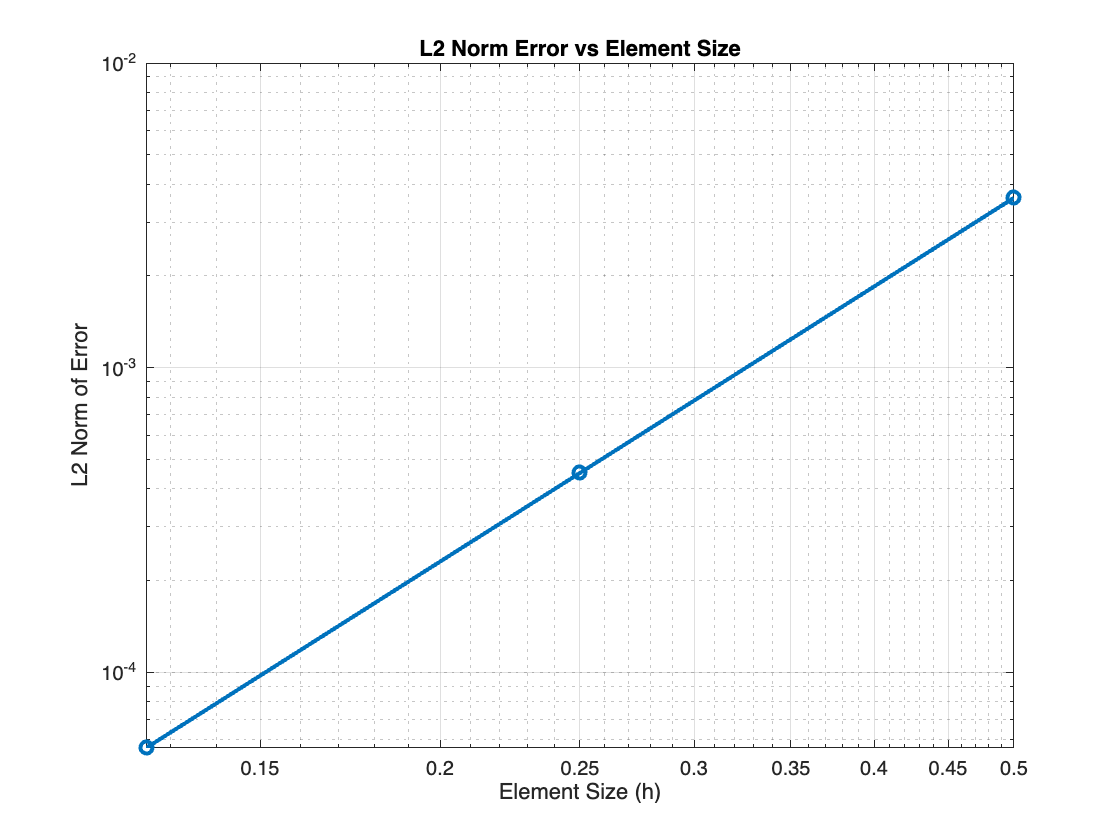

% Define the exact solution u(x) = x^3 as an anonymous function
exact_solution = @(x) x.^3;

% Define the Gauss quadrature points and weights for a 3-point rule
gauss_points = [-sqrt(3/5), 0, sqrt(3/5)];  % Gauss points in [-1, 1]
gauss_weights = [5/9, 8/9, 5/9];  % Weights for 3-point quadrature

% Initialize an array to store the L2 norm error for 2, 4, and 8 elements
error_L2 = zeros(3, 1);  % To store errors for each mesh size

% Define the mesh sizes
mesh_sizes = [2, 4, 8];
L = 1;  % Length of the domain

% Loop over each mesh size
for mesh_index = 1:length(mesh_sizes)
    num_elements = mesh_sizes(mesh_index);  % Get the number of elements
    element_length = L / num_elements;  % Compute the length of each element
    error_sum = 0;  % Initialize the error sum for this mesh size

    % Loop over each element
    for elem = 1:num_elements
        % Define element boundaries for the three nodes
        x1 = (elem - 1) * element_length;  % Left node of element
        x2 = x1 + element_length / 2;      % Middle node of element
        x3 = elem * element_length;        % Right node of element

        % Quadratic shape functions for the element
        u_h = @(x) ((x - x2)*(x - x3))/((x1 - x2)*(x1 - x3)) * exact_solution(x1) + ...
                   ((x - x1)*(x - x3))/((x2 - x1)*(x2 - x3)) * exact_solution(x2) + ...
                   ((x - x1)*(x - x2))/((x3 - x1)*(x3 - x2)) * exact_solution(x3);

        % Compute the squared error for each Gauss point
        for i = 1:length(gauss_points)
            % Map Gauss point to the actual element
            xi = ((x3 - x1) / 2) * gauss_points(i) + (x3 + x1) / 2;

            % Compute the error at the Gauss point
            error_at_gauss_point = (u_h(xi) - exact_solution(xi))^2;

            % Sum the contribution of this Gauss point
            error_sum = error_sum + gauss_weights(i) * error_at_gauss_point * (x3 - x1) / 2;
        end
    end

    % Store the L2 norm error for this mesh size
    error_L2(mesh_index) = sqrt(error_sum);
end

% Plot the error vs element size (log-log plot)
element_sizes = 1 ./ mesh_sizes;  % Element size = 1 / number of elements
figure;
loglog(element_sizes, error_L2, '-o', 'LineWidth', 2);
xlabel('Element Size (h)');
ylabel('L2 Norm of Error');
title('L2 Norm Error vs Element Size');
grid on;


% Optionally, compute the slope of the log-log plot (convergence rate)
p = polyfit(log(element_sizes), log(error_L2), 1);
fprintf('Slope of the log-log plot (rate of convergence): %.2f\n', p(1));

Slope of the log-log plot (rate of convergence): 3.00


I also tried to use your code and came up with the following:

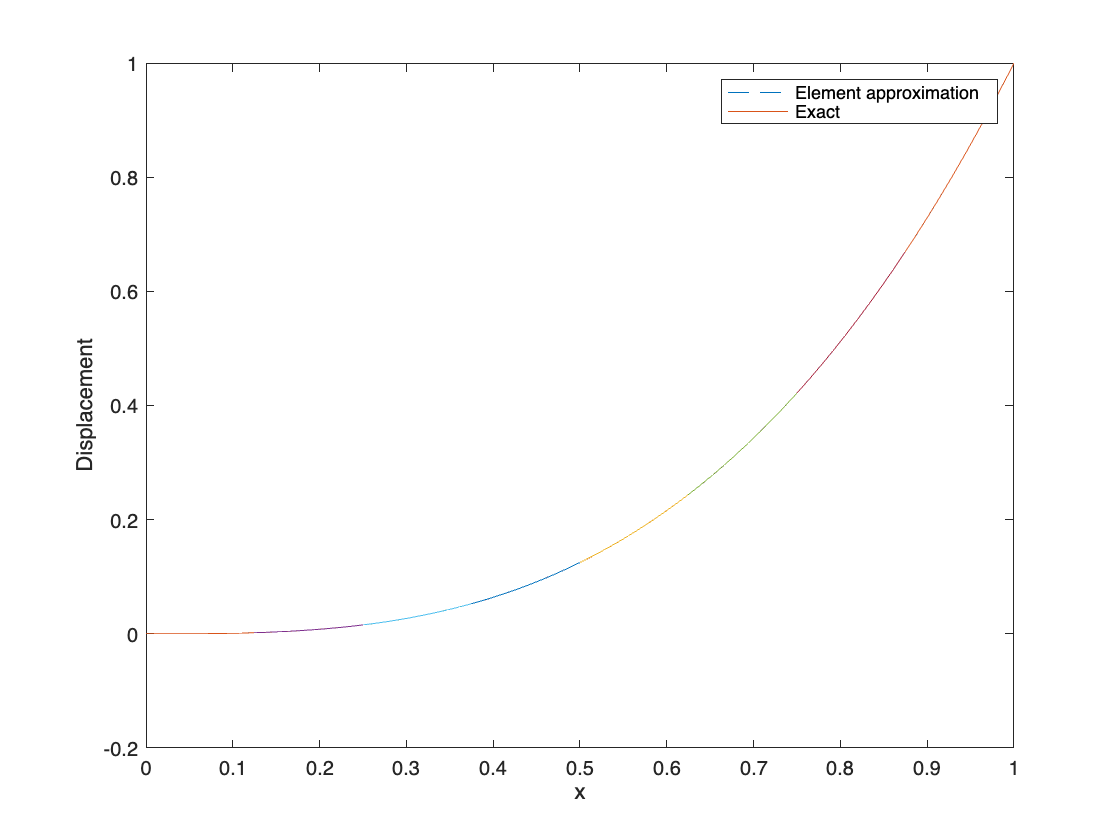

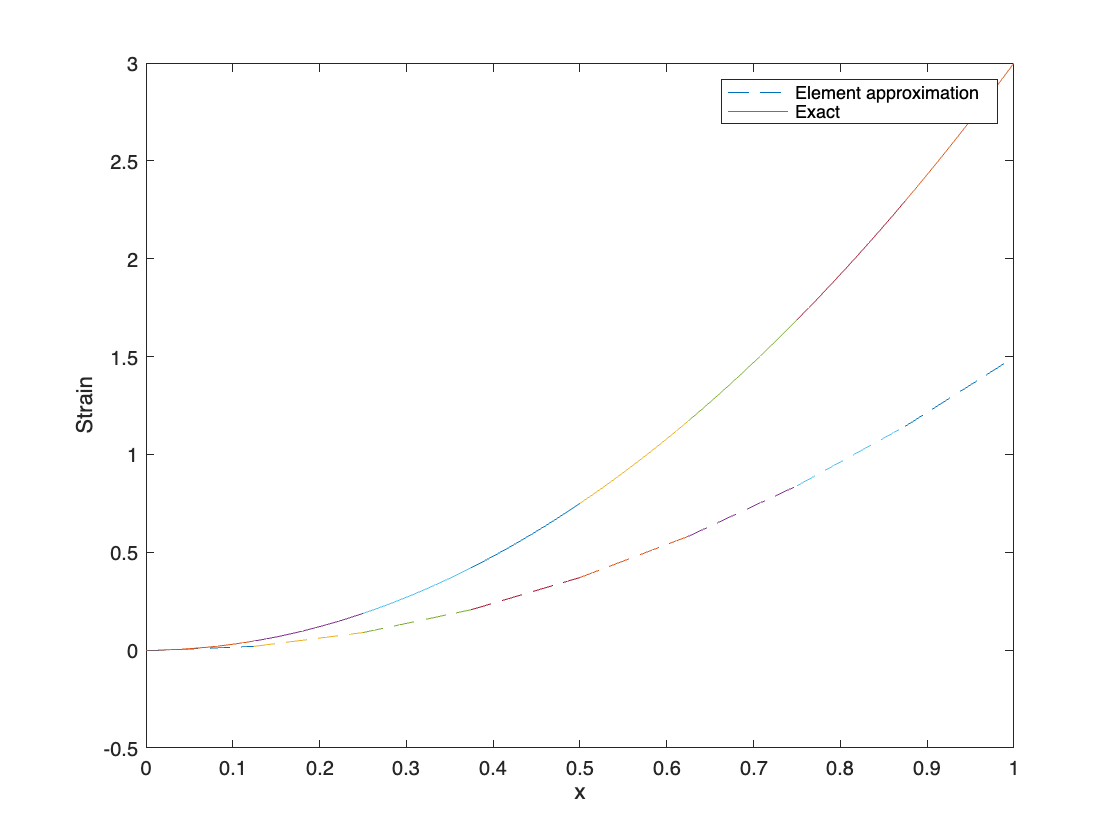


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% User input
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%Element type
% etype=1: linear 2 node element
% etype=2: quadratic 3 node element
etype = 2;  % Change this to 1 for linear elements, 2 for quadratic elements

% Number of elements
Nelem = 8;

% Number of points to plot within each element
Npp = 10;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% End User input
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Domain length
L = 1.0;

% 1 dof per node
Ndof = 1;

% Nnodes: number of nodes per element
% Nnodes_g: number of global nodes
if etype == 1
    Nnodes = 2;
    Nnodes_g = Nelem + 1;
else
    Nnodes = 3;  % 3-node quadratic element
    Nnodes_g = 2 * Nelem + 1;  % Global nodes for quadratic elements
end

% Element length in 1D; constant throughout here
dx = L / Nelem;

% Spacing between plotting points (Gauss quadrature domain [-1,1])
dxi_plot = 2.0 / (Npp - 1);

% Initialize arrays for node coordinates
xyz = zeros(Nnodes_g, 3);
for i = 1:Nnodes_g
    xyz(i,1) = (i-1)*(dx/(Nnodes-1));
end

% Define element node to global node mapping (adjusted for 3-node element)
elem_map = zeros(Nelem, Nnodes);
for i = 1:Nelem
    for j = 1:Nnodes
        elem_map(i,j) = (i-1)*2 + j;  % Adjusted for quadratic elements
    end
end

% Define total number of global dof
Ndof_tot = Nnodes_g * Ndof;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Initialize all arrays with zeros
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
D = zeros(Ndof_tot,1);
ue = zeros(Nelem,Npp);
uexact = zeros(Nelem,Npp);
ee = zeros(Nelem,Npp);
eexact = zeros(Nelem,Npp);
xe = zeros(Nelem,Npp);
Delem = zeros(Nnodes,1);
xelem = zeros(Nnodes,1);
xi = zeros(4,1);

f1 = figure;
f2 = figure;
err2 = 0.0;

% Assign values to D based on exact solution u_I=x_I^3
for i = 1:Ndof_tot
    D(i) = xyz(i,1)^3;
end

% Loop over elements
for i = 1:Nelem

    % Assign nodal displacements and positions using elem_map
    for j = 1:Nnodes
        Delem(j,1) = D(elem_map(i,j));
        xelem(j,1) = xyz(elem_map(i,j));
    end

    % Loop over element plotting points
    for j = 1:Npp

        % Plotting point (in -1 to 1 domain)
        xi(1) = -1.0 + (j-1) * dxi_plot;

        % Compute shape function and B matrix
        if etype == 1
            xe(i,j) = xelem(1,1) * 0.5 * (1.0 - xi(1)) + xelem(2,1) * 0.5 * (1.0 + xi(1));
            [N, B] = shape1d_lin(xe(i,j), xelem);
        elseif etype == 2
            % Correct quadratic mapping
            xe(i,j) = xelem(1,1) * (xi(1) * (xi(1) - 1)) / 2 + ...
                      xelem(2,1) * (1 - xi(1)^2) + ...
                      xelem(3,1) * (xi(1) * (xi(1) + 1)) / 2;
            [N, B] = shape1d_quad(xe(i,j), xelem);  % Use quadratic shape function
        end

        % Displacement and strain at xe(j)
        ue(i,j) = N * Delem;
        uexact(i,j) = xe(i,j)^3;
        ee(i,j) = B * Delem;
        eexact(i,j) = 3.0 * xe(i,j)^2;
    end

    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % Error calculation (Parts d and e)
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

    % Use four-point Gauss quadrature for exact solution (cubic)
    w = [0.3478548451, 0.3478548451, 0.6521451549, 0.6521451549];
    xi = [0.8611363116, -0.8611363116, 0.3399810436, -0.3399810436];

    % Element length
    if etype == 1
        le = xelem(2) - xelem(1);
    else
        le = xelem(3) - xelem(1);
    end

    % Jacobian for transformation between x and xi
    Jac = 0.5 * le;

    % Loop over Gauss quad points
    for j = 1:4
        if etype == 1
            xg = xelem(1,1) * 0.5 * (1.0 - xi(j)) + xelem(2,1) * 0.5 * (1.0 + xi(j));
            [N, B] = shape1d_lin(xg, xelem);
        elseif etype == 2
            xg = xelem(1,1) * (xi(j) * (xi(j) - 1)) / 2 + ...
                 xelem(2,1) * (1 - xi(j)^2) + ...
                 xelem(3,1) * (xi(j) * (xi(j) + 1)) / 2;
            [N, B] = shape1d_quad(xg, xelem);
        end

        % Approximation and exact solution at Gauss point
        ue_g = N * Delem;
        uexact_g = xg^3;

        % Compute error
        err2 = err2 + (uexact_g - ue_g)^2 * w(j) * Jac;
    end
end

% Plot results (parts a-c)
for i = 1:Nelem
    figure(f1)
    plot(xe(i,:), ue(i,:), '--', xe(i,:), uexact(i,:));
    legend('Element approximation', 'Exact');
    xlabel('x');
    ylabel('Displacement');
    hold on;
    figure(f2);
    plot(xe(i,:), ee(i,:), '--', xe(i,:), eexact(i,:));
    legend('Element approximation', 'Exact');
    xlabel('x');
    ylabel('Strain');
    hold on;
end


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Shape Function for 2-Node Linear Element
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function [N, B] = shape1d_lin(x, xelem)
    le = xelem(2) - xelem(1);  % Element length
    xi = (2*(x - xelem(1)) / le) - 1;  % Parametric coordinate in [-1, 1]

    % Shape functions for 2-node linear element
    N = [(1 - xi) / 2, (1 + xi) / 2];
    
    % Derivative of shape functions (B matrix)
    B = [-1 / le, 1 / le];
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Shape Function for 3-Node Quadratic Element
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function [N, B] = shape1d_quad(x, xelem)
    le = xelem(3) - xelem(1);  % Element length
    xi = 2 * (x - xelem(1)) / le - 1;  % Parametric coordinate in [-1, 1]

    % Shape functions for 3-node quadratic element
    N = [(xi*(xi-1))/2, (1-xi^2), (xi*(xi+1))/2];

    % Derivative of shape functions (B matrix)
    B = [(xi - 0.5), -2*xi, (xi + 0.5)] / le;
end



When you compare these to the linear approximations you see that there is a much greater accuracy. As the nodes increase and test functions  increase in their orders the accuracy improves drastically. I did try to run some plots to help compare but I was running into some coding problems and was running out of time.

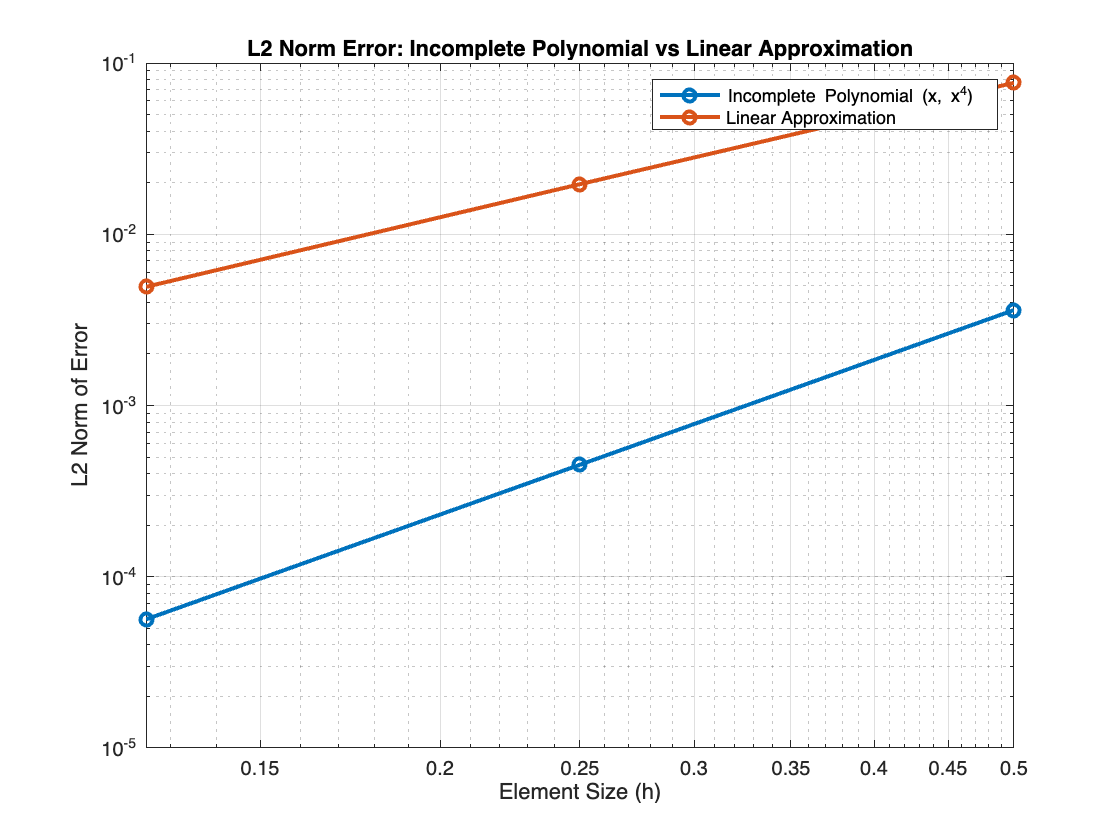

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Modified Code for a 3-node element with incomplete polynomial approximation
% \sigma^{e} = \alpha_0^{e} + \alpha_1^{e} x + \alpha_2^{e} x^4
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


% Define the exact solution u(x) = x^3 as an anonymous function
exact_solution = @(x) x.^3;

% Define the Gauss quadrature points and weights for a 3-point rule
gauss_points = [-sqrt(3/5), 0, sqrt(3/5)];  % Gauss points in [-1, 1]
gauss_weights = [5/9, 8/9, 5/9];  % Weights for 3-point quadrature

% Initialize an array to store the L2 norm error for 2, 4, and 8 elements
error_L2_incomplete = zeros(3, 1);  % Error for incomplete polynomial
error_L2_linear = zeros(3, 1);  % Error for linear approximation

% Define the mesh sizes
mesh_sizes = [2, 4, 8];
L = 1;  % Length of the domain

% Loop over each mesh size
for mesh_index = 1:length(mesh_sizes)
    num_elements = mesh_sizes(mesh_index);  % Get the number of elements
    element_length = L / num_elements;  % Compute the length of each element
    error_sum_incomplete = 0;  % Initialize error sum for incomplete polynomial
    error_sum_linear = 0;  % Initialize error sum for linear approximation

    % Loop over each element
    for elem = 1:num_elements
        % Define element boundaries and mid-point
        x1 = (elem - 1) * element_length;  % Left node of element
        x3 = elem * element_length;        % Right node of element
        x2 = (x1 + x3) / 2;               % Mid-point of element

        % Finite element approximation using incomplete polynomial (x, x^4)
        N1_incomplete = @(x) (x - x2) * (x - x3) / ((x1 - x2) * (x1 - x3));
        N2_incomplete = @(x) (x - x1) * (x - x3) / ((x2 - x1) * (x2 - x3));
        N3_incomplete = @(x) (x - x1) * (x - x2) / ((x3 - x1) * (x3 - x2));

        u_h_incomplete = @(x) N1_incomplete(x) * exact_solution(x1) + N2_incomplete(x) * exact_solution(x2) + N3_incomplete(x) * exact_solution(x3);

        % Linear approximation for comparison
        u_h_linear = @(x) ((x3 - x) / element_length) * exact_solution(x1) + ((x - x1) / element_length) * exact_solution(x3);

        % Compute the squared error for each Gauss point
        for i = 1:length(gauss_points)
            % Map Gauss point to the actual element
            xi = ((x3 - x1) / 2) * gauss_points(i) + (x3 + x1) / 2;

            % Error for incomplete polynomial approximation
            error_at_gauss_point_incomplete = (u_h_incomplete(xi) - exact_solution(xi))^2;

            % Error for linear approximation
            error_at_gauss_point_linear = (u_h_linear(xi) - exact_solution(xi))^2;

            % Sum the contributions of this Gauss point
            error_sum_incomplete = error_sum_incomplete + gauss_weights(i) * error_at_gauss_point_incomplete * (x3 - x1) / 2;
            error_sum_linear = error_sum_linear + gauss_weights(i) * error_at_gauss_point_linear * (x3 - x1) / 2;
        end
    end

    % Store the L2 norm errors for this mesh size
    error_L2_incomplete(mesh_index) = sqrt(error_sum_incomplete);
    error_L2_linear(mesh_index) = sqrt(error_sum_linear);
end

% Plot the error vs element size (log-log plot) for both approximations
element_sizes = 1 ./ mesh_sizes;  % Element size = 1 / number of elements

figure;
loglog(element_sizes, error_L2_incomplete, '-o', 'LineWidth', 2, 'DisplayName', 'Incomplete Polynomial (x, x^4)');
hold on;
loglog(element_sizes, error_L2_linear, '-o', 'LineWidth', 2, 'DisplayName', 'Linear Approximation');
xlabel('Element Size (h)');
ylabel('L2 Norm of Error');
title('L2 Norm Error: Incomplete Polynomial vs Linear Approximation');
legend show;
grid on;


% Optionally, compute and print the slopes of the log-log plots (rate of convergence)
p_incomplete = polyfit(log(element_sizes), log(error_L2_incomplete), 1);
p_linear = polyfit(log(element_sizes), log(error_L2_linear), 1);
fprintf('Slope of log-log plot (rate of convergence for incomplete polynomial): %.2f\n', p_incomplete(1));

Slope of log-log plot (rate of convergence for incomplete polynomial): 3.00


fprintf('Slope of log-log plot (rate of convergence for linear approximation): %.2f\n', p_linear(1));

Slope of log-log plot (rate of convergence for linear approximation): 1.98


Here is another attempt at trying to analyze the error of the element size. I think that this may be the best of the graphical representations.